# Set Up

clc;
close all;
clear;



## Load and configure data

% Load subject data (R1)
test = 1;
edfFilename = sprintf('R%d_edf.mat', test);
xmlFilename = sprintf('R%d_xml.mat', test);
load(edfFilename);   % loads 'record' and 'hdr'
load(xmlFilename);   % loads 'stages'

Fs = hdr.samples(3);       % Sampling frequency
epochLength = 30;          % Duration of each epoch in seconds
numberOfEpochs = floor(length(record(5,:)) / (Fs * epochLength)) - 1;  % Based on EMG channel


## Signal extraction (EEG + EOG + EMG)

% Channel indices
eeg_channel = 3;
eog_channel = 6;     % or 7 if using EOGR
emg_channel = 5;

% Initialize epoch matrices
EEG = zeros(numberOfEpochs, Fs * epochLength);
EOG = zeros(numberOfEpochs, Fs * epochLength);
EMG_raw = zeros(numberOfEpochs, Fs * epochLength);

for i = 1:numberOfEpochs
    epochStart = i * Fs * epochLength;
    epochEnd = epochStart + Fs * epochLength - 1;

    EEG(i,:) = record(eeg_channel, epochStart:epochEnd);
    EOG(i,:) = record(eog_channel, epochStart:epochEnd);
    EMG_raw(i,:) = record(emg_channel, epochStart:epochEnd);
end



## EMG preprocessing

[EMG_clean, EMG_envelope] = preprocess_emg(EMG_raw, Fs);

## Plot (example)

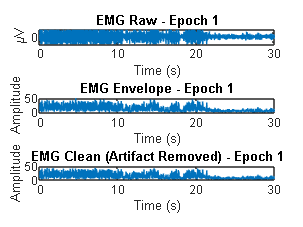

t = (1:Fs*epochLength)/Fs;
figure;

% EMG - Raw signal
subplot(3,1,1);
plot(t, EMG_raw(1,:));
title('EMG Raw - Epoch 1'); xlabel('Time (s)'); ylabel('\muV');

% EMG - Envelope
subplot(3,1,2);
plot(t, EMG_envelope(1,:));
title('EMG Envelope - Epoch 1'); xlabel('Time (s)'); ylabel('Amplitude');

% EMG - Clean (after artifact removal)
subplot(3,1,3);
plot(t, EMG_clean(1,:));
title('EMG Clean (Artifact Removed) - Epoch 1'); xlabel('Time (s)'); ylabel('Amplitude');


set(gcf, 'color', 'w');
